# Computer Vision Lab 2

# Edges and contours

**Authors**: Jorge Alexander and Emer Rodriguez Formisano

**Date**: 23th October 2017

## 1. Determine the optimal edges

Create a file "exercise1.m" to implement the following steps:

    1.1 Read the image "starbuck.jpg" and find its edges using matlab function edge.

    1.2 Apply different operators (Sobel and Prewitt, Laplacian of Gaussian) and find the optimal parameters for each of them.

    1.3 Apply Canny edge detector (also implemented in the function edge).

    1.4 Overlap the edges on the image as shown in Fig.2 (right).

    1.5 Repeat the experiment on 3 other images.

The function **showedges** applies the previous points programatically for each imge and plots the results:

**Starbucks**

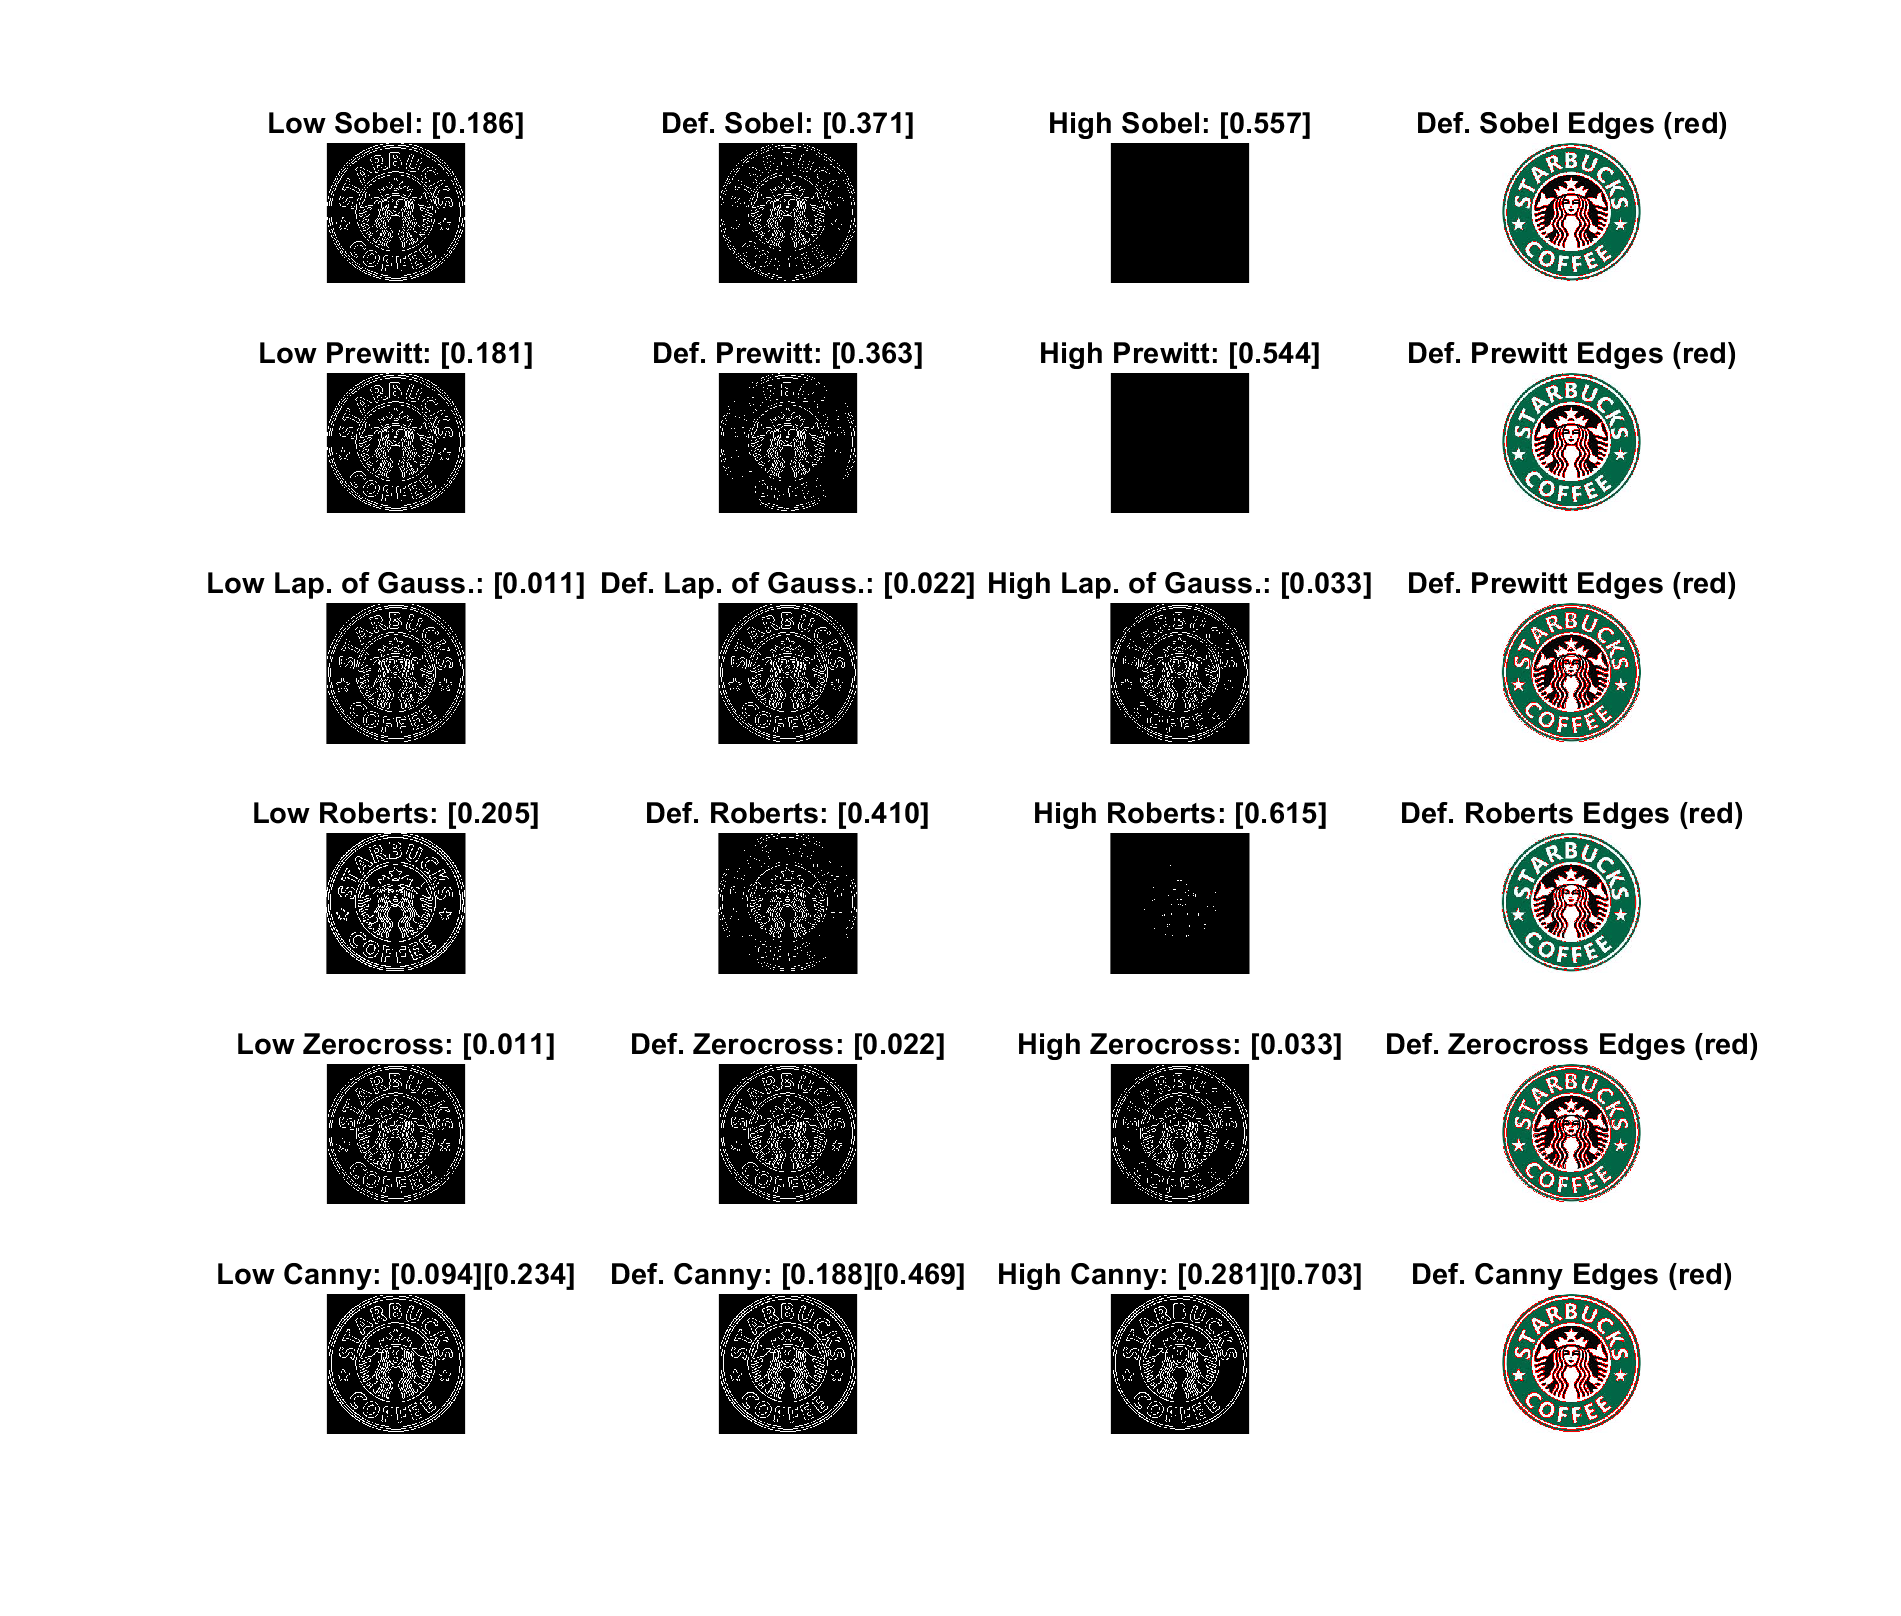

set(gcf,'Position',[0 0 1000 850]);
showedges('./images_video/starbuck.jpg')

**Doulphin**

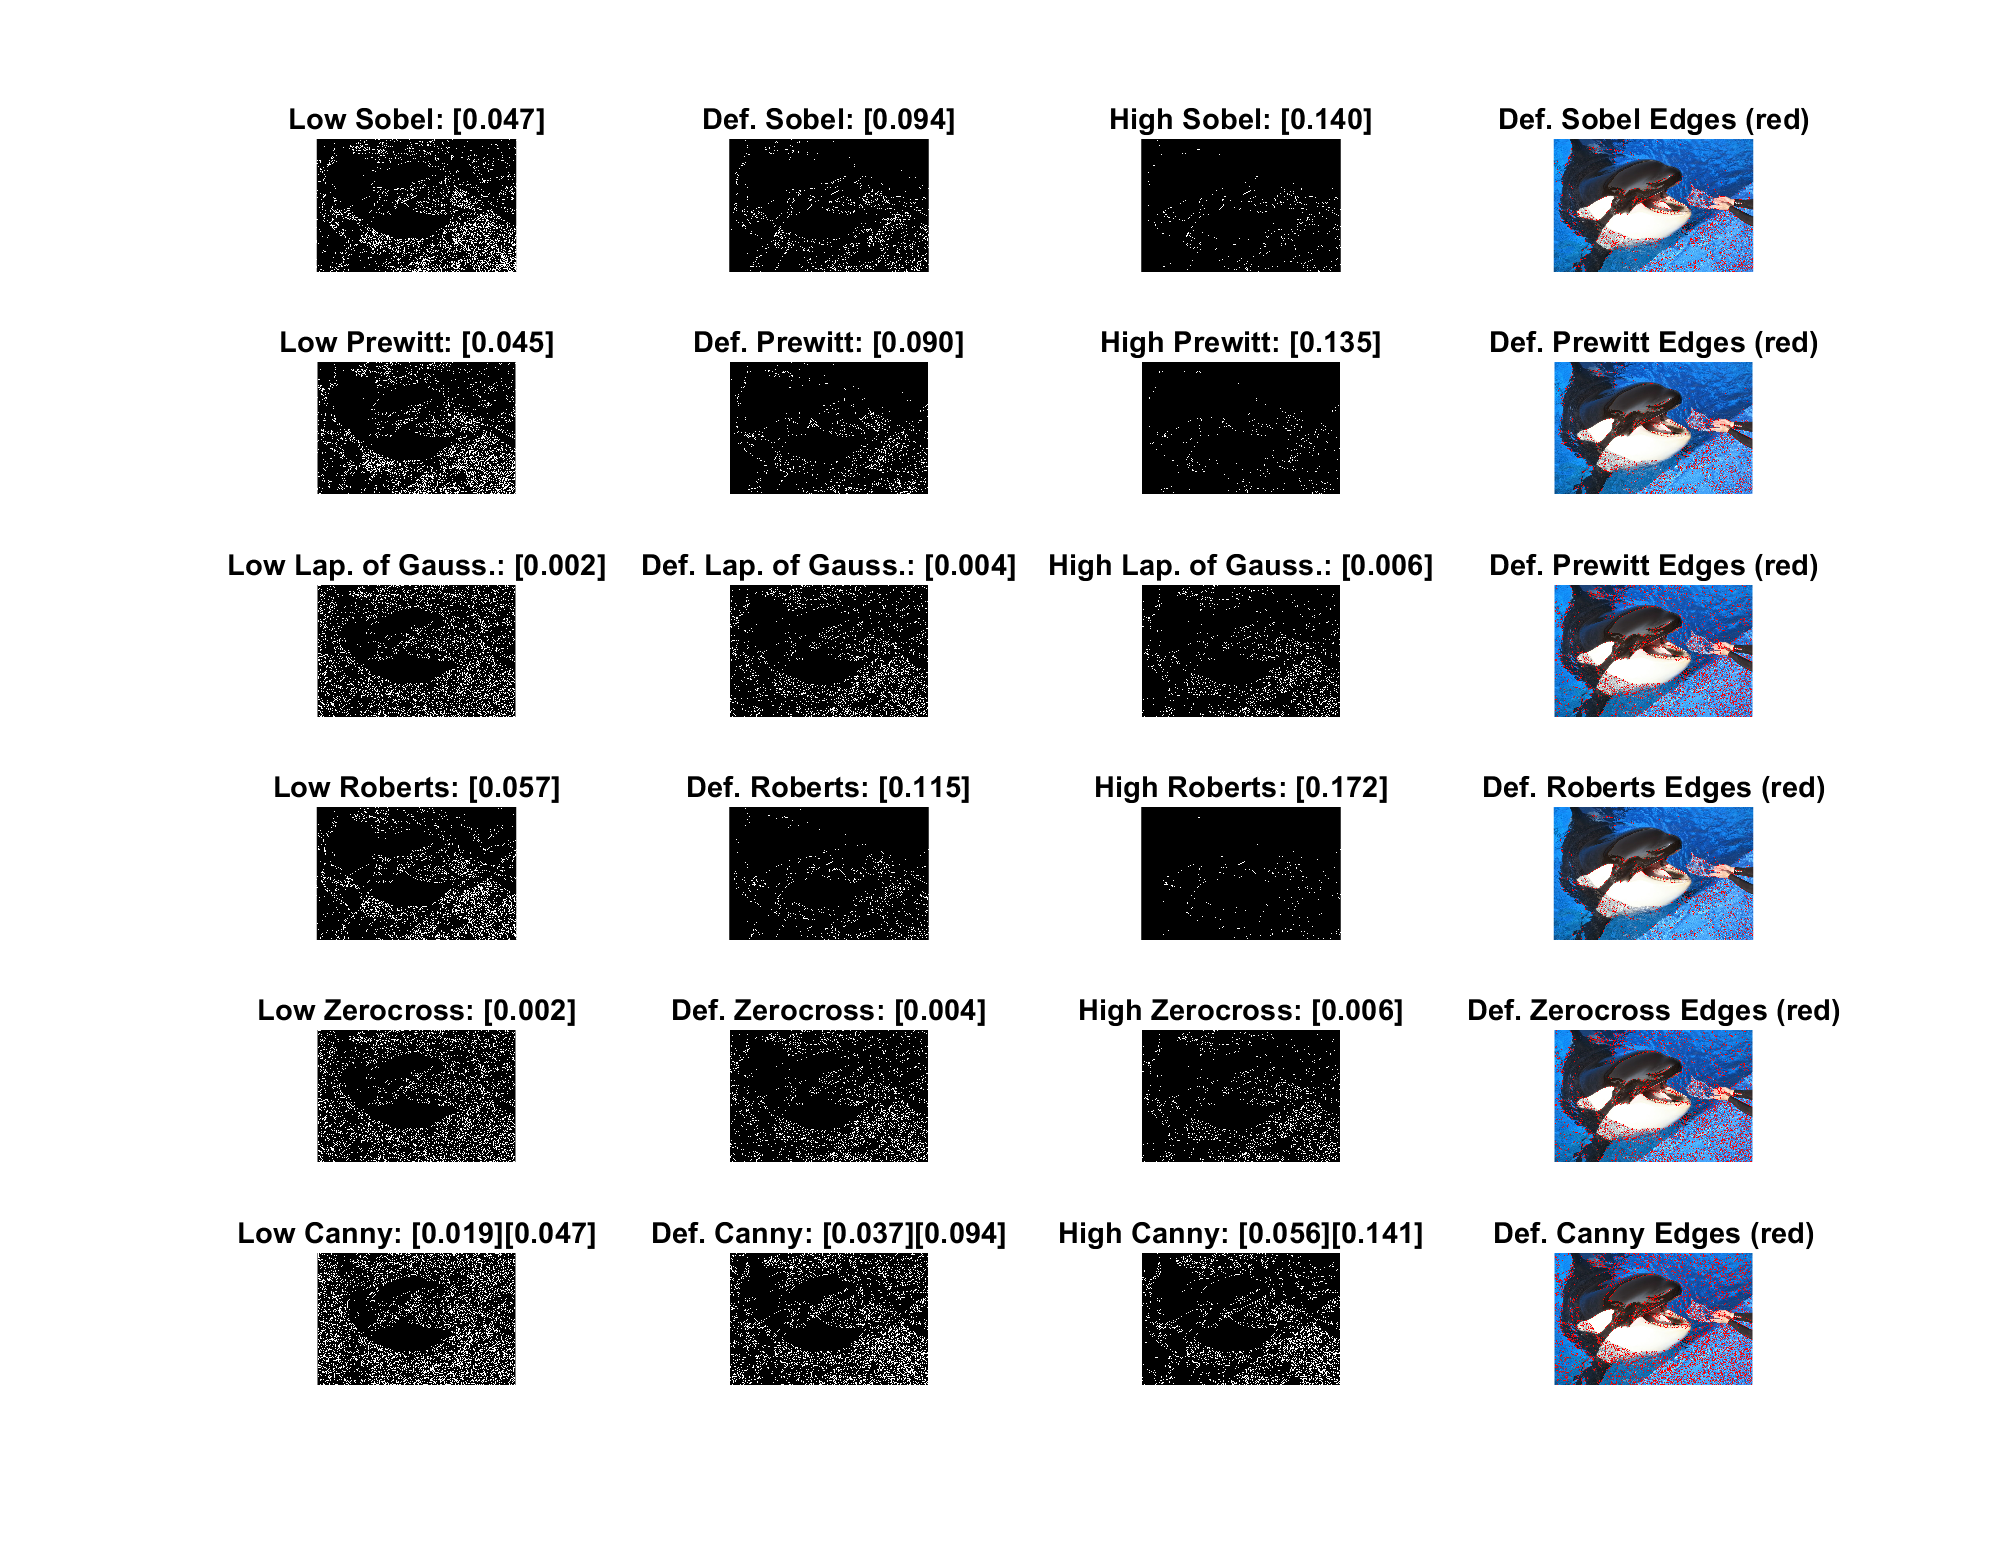

showedges('./images_video/Doulphin.jpg')

**Einstein**

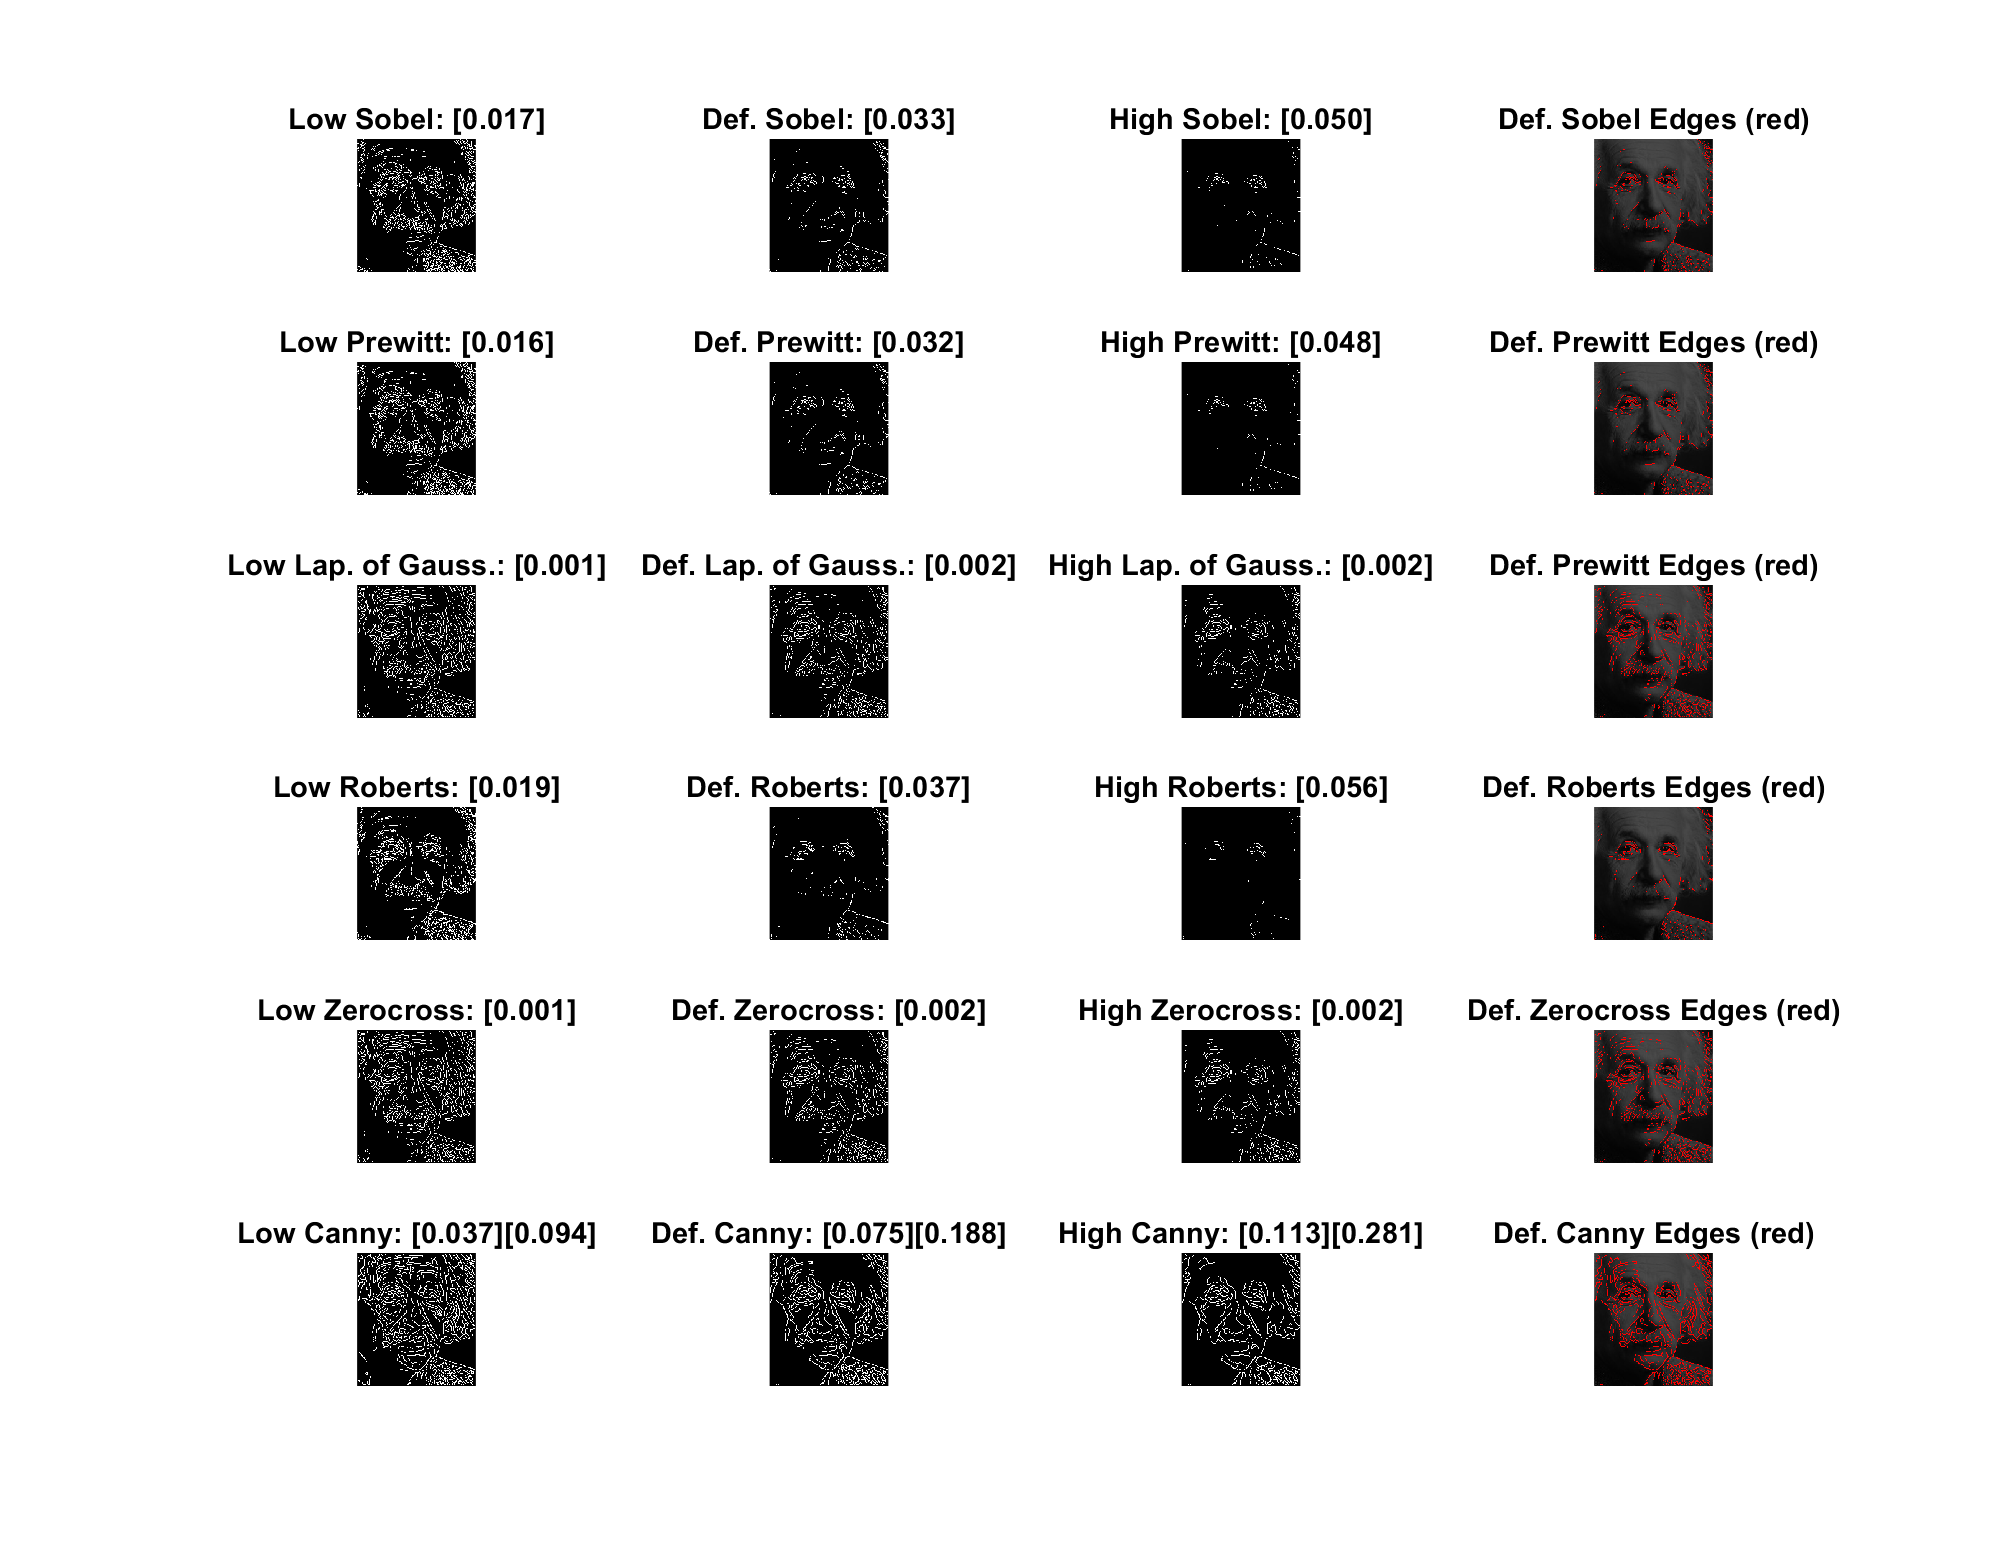

showedges('./images_video/Einstein.jpg')

Answer the following questions in the report:

1. How many methods to obtain the edges of the image are implemented by the function edge?

    There are 6: Sobel, Prewitt, Laplacian of Gaussian, Roberts, Zerocross and Canny.

2. Which is the best edge detector?

    It depends on the image and how well the detectors parameters are tuned. For example, the Canny detector has parameter sigma, which controls the size of the Gaussian filter. The higher the parameter's value, the wider the Gaussian filter becomes. The larger the Gaussian filter, the more blurring. This is good for noisy images, but will not be so good at detecting thin edges. Other algorithms, such as Sobel, are more sensitive to noise, meaning that the processed images often have over-defined edges, or in places where there are no objects. 

3. What are the advantages and disadvantages you see when extracting the edges on the different images?

The advantage of edge extraction is a better definition of objects in the image. However, there are disadvantages when an object does not have well defined edges and is not detected, or when object definition is not the information that is trying to be extracted from the image. For example, when viewing a classic painting by Claude Monet, the edges are not well defined and the idea is that you experience the painting by viewing it from afar and allowing the colours to merge together. If the painting were to be processed with edge extraction algorithms, the colours would not merge into each other from afar as ther would be sharp edges separating them. 

4. Discuss if the parameters should be changed for the different images.

    The parameters allow for a better edge detection based on different types of images and therefore should be changed if edge detection is to be optimal. This is because, for example, two images with different intensities of lighting will react better to different threshold values for edge detection. If we want to ensure that we extract the optimal edges for each one, we should vary the threshold value when processing each one.

## 2 Enhancing images with edges

Overlapping edges on images are sometimes used in order to enhance the main structures of the images, perceive better the motion of the objects and for other visual effects. Create a file "exercise2.m" to implement the following steps:

- Read the video video Maldives.mp4 (Help: VideoReader).

% First the video object is loaded with the video file
vidObj = VideoReader('images_video/Maldives.mp4');
% Next the first frame is read and saved
frame = readFrame(vidObj);
imwrite(frame, 'frame_1.jpg');
imshow(frame), title("Frame")

- Enhance the edges and overlap them on the video Maldives.mp4.

The first frame is analysed using the showedges function that was defined in the previous exercise. 

set(gcf,'Position',[0 0 1000 850]);
showedges('frame_1.jpg');

The output shows the defaults (Def) parameters estimated by the matlab function using heuristics. Low is the default parameters descreased by 0.5 less while High is default parameter increased by 1.5.

- Show the video with the extracted contours as movie.

% Canny is seen to give good edge detection    
sigma = 2;
[canny, thresh] = edge(rgb2gray(frame), 'Canny', [], sigma);
canny = edge(rgb2gray(frame), 'Canny', thresh);
highlightedFrame = overlapedges(frame, canny);
imshow(highlightedFrame);

Here the video is edited and saved with highlighted edges using Canny edge detection with sigma=2 and thresh=[0.1250, 0.1625]

reader = VideoReader('images_video/Maldives.mp4');
writer = VideoWriter('images_video/maldivesContour.mp4', 'MPEG-4');
writer.FrameRate = reader.FrameRate;
open(writer);
sigma = 2;
thresh = [0.1250, 0.1625];
while hasFrame(reader)
    frame = readFrame(reader);
    canny = edge(rgb2gray(frame), 'Canny', thresh, sigma);
    frame = overlapedges(frame, canny);
    writeVideo(writer, frame);
end
close(writer);

If we open the edited video, the edges of objects are observed more clearly. This is particularly useful for identifying and generating actions from the objects in the image, for example, car detection.

Answer the following questions in the report:

1. Save some frames of the video with the extracted contours.

Task done in the previous section.

2. Discuss which is the best way to obtain the edges and check which are the best parameters.

3. What advantages and disadvantages do you see on the obtained effect?

There are several ways to obtain edges. The best seems to be to allow Matlab to choose the default values, and then proceed to tweak the parameters with small increments, higher and lower. In the analysis of frame 1 the effect of a low, default and high threshold value is observed. It shows that when a low threshold value is chosen, the edge sensitivity is high, and more edges are detected. This can be a disadvantage if there is noise in the image, as it may be wrongly detected as an edge. With a high threshold however, the edge sensitivity is low, and less edges are detected. This is good for finding objects with sharp, well-defined edges, but other objects which are blurry or less defined may not have its edges detected.

## Defined Function

function overlapedImage = overlapedges(rgbImage, edges)
    redCh = rgbImage(:,:,1);
    greenCh = rgbImage(:,:,2);
    blueCh = rgbImage(:,:,3);
    redCh(edges) = 255;
    greenCh(edges) = 0;
    blueCh(edges) = 0;
    overlapedImage = cat(3, redCh, greenCh, blueCh);      
end

function showedges(imageFilename)
%UNTITLED2 Summary of this function goes here
%   Detailed explanation goes here

    function overlapedImage = overlapedges(rgbImage, edges)
        redCh = rgbImage(:,:,1);
        greenCh = rgbImage(:,:,2);
        blueCh = rgbImage(:,:,3);
        redCh(edges) = 255;
        greenCh(edges) = 0;
        blueCh(edges) = 0;
        overlapedImage = cat(3, redCh, greenCh, blueCh);      
    end

rawImage = imread(imageFilename);
if(ndims(rawImage)==2)
    ch = rawImage ./ 3;
    % Gray as RGB representation
    rawImage = cat(3, ch, ch, ch);
end
rawImageGray = rgb2gray(rawImage);

fixedThres = [];
multThres = [0.5, 1.5];
sigma = 2;
direction = 'both';
thinning = 'thinning'; 
% Sobel
[sobel, sobelThres] = edge(rawImageGray, 'Sobel', fixedThres, direction, thinning);
[sobelLow, sobelThresLow] = edge(rawImageGray, 'Sobel', sobelThres * multThres(1), direction, thinning);
[sobelHigh, sobelThresHigh] = edge(rawImageGray, 'Sobel', sobelThres * multThres(2), direction, thinning);

% Prewitt
[prewitt, prewittThres] = edge(rawImageGray, 'Prewitt', fixedThres, direction, thinning);
[prewittLow, prewittThresLow] = edge(rawImageGray, 'Prewitt', prewittThres * multThres(1), direction, thinning);
[prewittHigh, prewittThresHigh] = edge(rawImageGray, 'Prewitt', prewittThres * multThres(2), direction, thinning);

% Lapacian of Gaussian
[log, logThres] = edge(rawImageGray, 'log', fixedThres, sigma);
[logLow, logThresLow] = edge(rawImageGray, 'log', logThres * multThres(1), sigma);
[logHigh, logThresHigh] = edge(rawImageGray, 'log', logThres * multThres(2), sigma);

% Roberts
[roberts, robertsThres]  = edge(rawImageGray, 'Roberts', fixedThres);
[robertsLow, robertsThresLow]  = edge(rawImageGray, 'Roberts', robertsThres * multThres(1));
[robertsHigh, robertsThresHigh]  = edge(rawImageGray, 'Roberts', robertsThres * multThres(2));

% ZeroCross
[zerocross, zerocrossThres] = edge(rawImageGray, 'zerocross', fixedThres);
[zerocrossLow, zerocrossThresLow] = edge(rawImageGray, 'zerocross', zerocrossThres * multThres(1));
[zerocrossHigh, zerocrossThresHigh] = edge(rawImageGray, 'zerocross', zerocrossThres * multThres(2));

% Canny
[canny, cannyThres] = edge(rawImageGray, 'Canny', fixedThres);
[cannyLow, cannyThresLow] = edge(rawImageGray, 'Canny', cannyThres * multThres(1));
[cannyHigh, cannyThresHigh] = edge(rawImageGray, 'Canny', cannyThres * multThres(2));

% Plots
subplot(6,4,1), imshow(sobelLow), title("Low Sobel: " + sprintf("[%.3f]",string(sobelThresLow))), ... 
subplot(6,4,2), imshow(sobel), title("Def. Sobel: " + sprintf("[%.3f]",string(sobelThres))), ... 
subplot(6,4,3), imshow(sobelHigh), title("High Sobel: " + sprintf("[%.3f]",string(sobelThresHigh))), ... 
subplot(6,4,4), imshow(overlapedges(rawImage, sobel)), title("Def. Sobel Edges (red)"), ...

subplot(6,4,5), imshow(prewittLow), title("Low Prewitt: " + sprintf("[%.3f]",string(prewittThresLow))), ... 
subplot(6,4,6), imshow(prewitt), title("Def. Prewitt: " + sprintf("[%.3f]",string(prewittThres))), ... 
subplot(6,4,7), imshow(prewittHigh), title("High Prewitt: " + sprintf("[%.3f]",string(prewittThresHigh))), ... 
subplot(6,4,8), imshow(overlapedges(rawImage, prewitt)), title("Def. Prewitt Edges (red)"), ...

subplot(6,4,9), imshow(logLow), title("Low Lap. of Gauss.: " + sprintf("[%.3f]",string(logThresLow))), ... 
subplot(6,4,10), imshow(log), title("Def. Lap. of Gauss.: " + sprintf("[%.3f]",string(logThres))), ... 
subplot(6,4,11), imshow(logHigh), title("High Lap. of Gauss.: " + sprintf("[%.3f]",string(logThresHigh))), ... 
subplot(6,4,12), imshow(overlapedges(rawImage, log)), title("Def. Prewitt Edges (red)"), ...

subplot(6,4,13), imshow(robertsLow), title("Low Roberts: " + sprintf("[%.3f]",string(robertsThresLow))), ... 
subplot(6,4,14), imshow(roberts), title("Def. Roberts: " + sprintf("[%.3f]",string(robertsThres))), ... 
subplot(6,4,15), imshow(robertsHigh), title("High Roberts: " + sprintf("[%.3f]",string(robertsThresHigh))), ... 
subplot(6,4,16), imshow(overlapedges(rawImage, roberts)), title("Def. Roberts Edges (red)"), ...

subplot(6,4,17), imshow(zerocrossLow), title("Low Zerocross: " + sprintf("[%.3f]",string(zerocrossThresLow))), ... 
subplot(6,4,18), imshow(zerocross), title("Def. Zerocross: " + sprintf("[%.3f]",string(zerocrossThres))), ... 
subplot(6,4,19), imshow(zerocrossHigh), title("High Zerocross: " + sprintf("[%.3f]",string(zerocrossThresHigh))), ... 
subplot(6,4,20), imshow(overlapedges(rawImage, zerocross)), title("Def. Zerocross Edges (red)"), ...

subplot(6,4,21), imshow(cannyLow), title("Low Canny: " + sprintf("[%.3f]",string(cannyThresLow))), ... 
subplot(6,4,22), imshow(canny), title("Def. Canny: " + sprintf("[%.3f]",string(cannyThres))), ... 
subplot(6,4,23), imshow(cannyHigh), title("High Canny: " + sprintf("[%.3f]",string(cannyThresHigh))), ... 
subplot(6,4,24), imshow(overlapedges(rawImage, canny)), title("Def. Canny Edges (red)");

end
